# Présentation sur les spectrogrammes

Fe = 100; % Fréquence d'échantillonnage
t  = 0 : 1/Fe : 60-1/Fe; % Vecteur des temps
f1 = 20 * ones(size(t)); % f1 = 20Hz
f2 = [21*ones(1,length(t)/2), ...
      31*ones(1,length(t)/2)];
  
x  = sin(2*pi*f1.*t) + sin(2*pi*f2.*t);

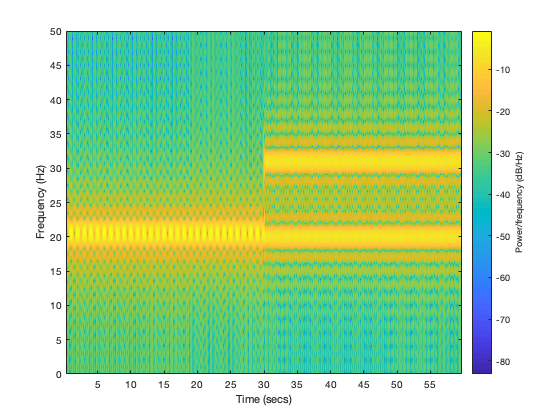

win = ones(1,50);
spectrogram(x, win, 49, 2048, Fe, 'yaxis')% 'centered'

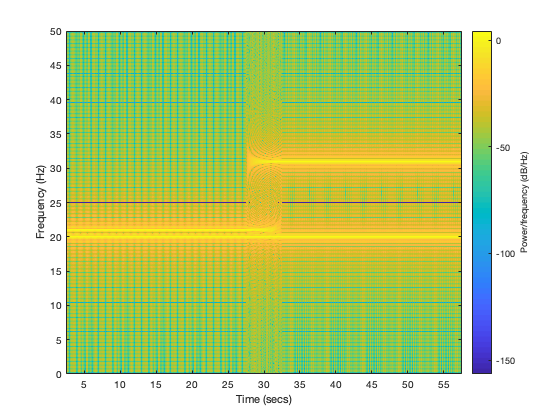

win = ones(1,500);
spectrogram(x, win, 499, 2048, Fe, 'yaxis')

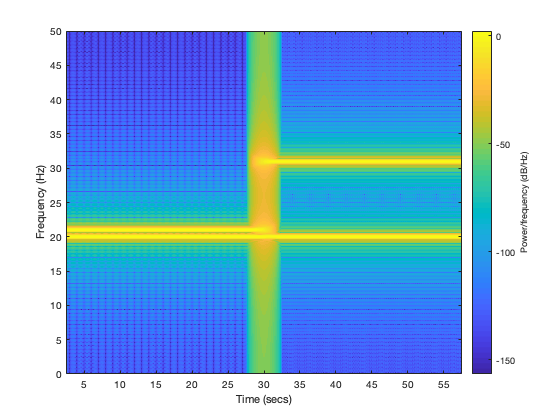

win = hann(500);
spectrogram(x, win, 499, 2048, Fe, 'yaxis')

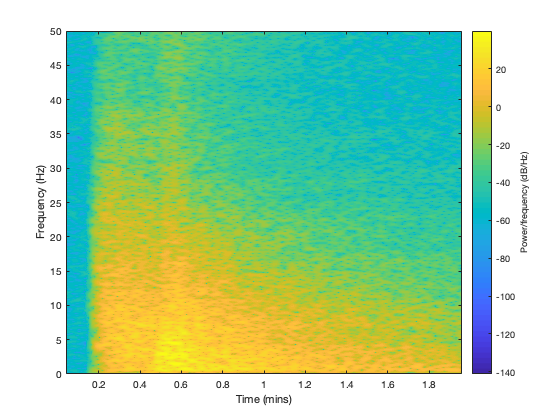

load list1.mat
spectrogram(list(5).sismo(:,1), win, 499, 2048, Fe, 'yaxis')